# Growth Kinetics Analaysis

clear;
clc;

## Wild Type

### n=1

WT_1 = "/Users/Priya/testoutput/TestMammaryOrganoid/MammaryCellCycleModel/WT/n=1/results_from_time_0/location.dat";
[WT_1_numberofcells, x, WT_1_yLE, WT_1_yME, WT_1_yTotal, WT_1_ME, WT_1_LE] = TimeVsNoCells(WT_1);

### n=2

WT_2 = "/Users/Priya/testoutput/TestMammaryOrganoid/MammaryCellCycleModel/WT/n=2/results_from_time_0/location.dat";
[WT_2_numberofcells, x, WT_2_yLE, WT_2_yME, WT_2_yTotal, WT_2_ME, WT_2_LE] = TimeVsNoCells(WT_2);

### n=3

WT_3 = "/Users/Priya/testoutput/TestMammaryOrganoid/MammaryCellCycleModel/WT/n=3/results_from_time_0/location.dat";
[WT_3_numberofcells, x, WT_3_yLE, WT_3_yME, WT_3_yTotal, WT_3_ME, WT_3_LE] = TimeVsNoCells(WT_3);

### n=4

WT_4 = "/Users/Priya/testoutput/TestMammaryOrganoid/MammaryCellCycleModel/WT/n=4/results_from_time_0/location.dat";
[WT_4_numberofcells, x, WT_4_yLE, WT_4_yME, WT_4_yTotal, WT_4_ME, WT_4_LE] = TimeVsNoCells(WT_4);

### n=5

WT_5 = "/Users/Priya/testoutput/TestMammaryOrganoid/MammaryCellCycleModel/WT/n=5/results_from_time_0/location.dat";
[WT_5_numberofcells, x, WT_5_yLE, WT_5_yME, WT_5_yTotal, WT_5_ME, WT_5_LE] = TimeVsNoCells(WT_5);

% combine data tables from all experiments into one table

yTotal_WT = cat(2,WT_1_yTotal,WT_2_yTotal,WT_3_yTotal,WT_4_yTotal,WT_5_yTotal);
yLE_WT = cat(2,WT_1_yLE,WT_2_yLE,WT_3_yLE,WT_4_yLE,WT_5_yLE);
yME_WT = cat(2,WT_1_yME,WT_2_yME,WT_3_yME,WT_4_yME,WT_5_yME);

% transpose data table
time = x.';
yTotal_WT_ = yTotal_WT.';
yLE_WT_ = yLE_WT.';
yME_WT_ = yME_WT.';

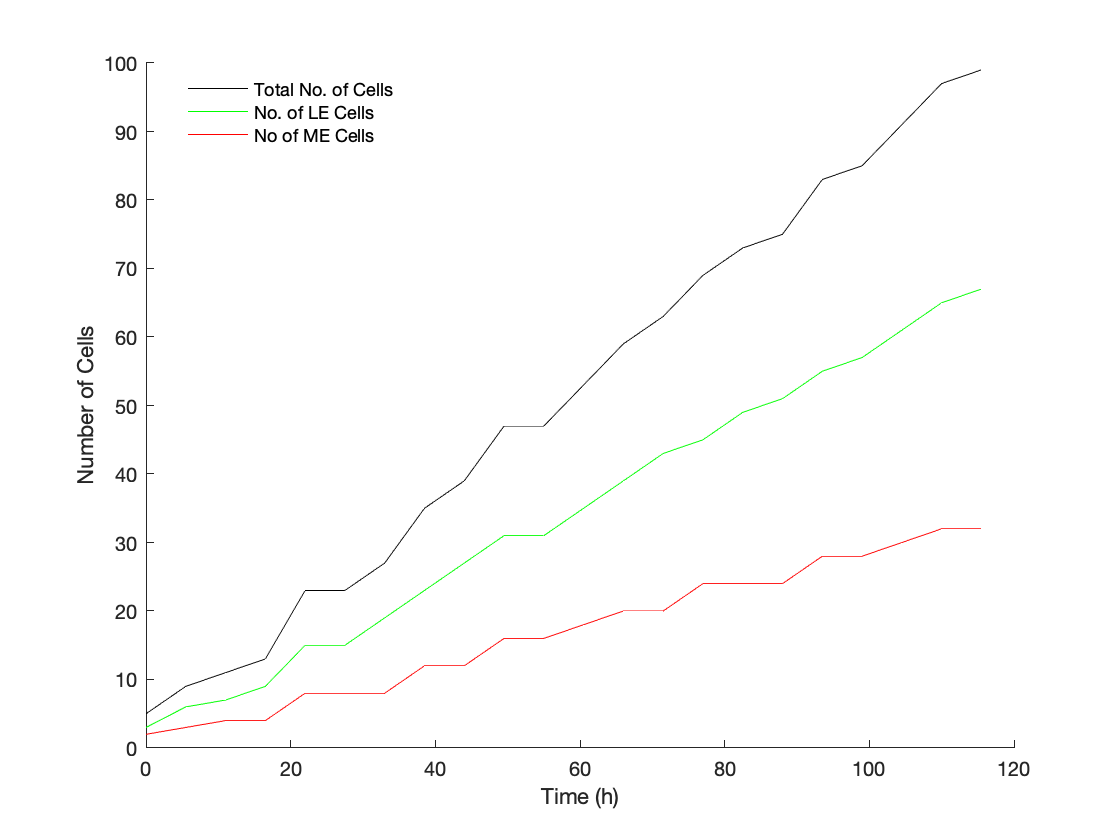

% plot data with error bars
clf

hold on; 

total = shadedErrorBar(time(:,1:55:end),yTotal_WT_(:,1:55:end),{@mean,@std},'lineProps','k','transparent',0);

hold off;

hold on;

LE = shadedErrorBar(time(:,1:55:end),yLE_WT_(:,1:55:end),{@mean,@std},'lineProps','-g','transparent',1);
hold off;

hold on;

ME = shadedErrorBar(time(:,1:55:end),yME_WT_(:,1:55:end),{@mean,@std},'lineProps','-r','transparent',1);

hold off;

ylabel ('Number of Cells')
xlabel('Time (h)')
legend({'Total No. of Cells', 'No. of LE Cells', 'No of ME Cells'}, 'location', 'best')
legend('boxoff')

folder = '~/Desktop/';
exportgraphics(gca, 'FigureCellsvsTime.pdf');
movefile('FigureCellsvsTime.pdf', folder);

% [WTnumberofcells] = CellCount_Graph(WT);